## Exercise 1.2

$y^{\prime } =\cos \left(x\right),y\left(0\right)=2$ Solving the ODE we can get $y=\sin \left(x\right)+2$

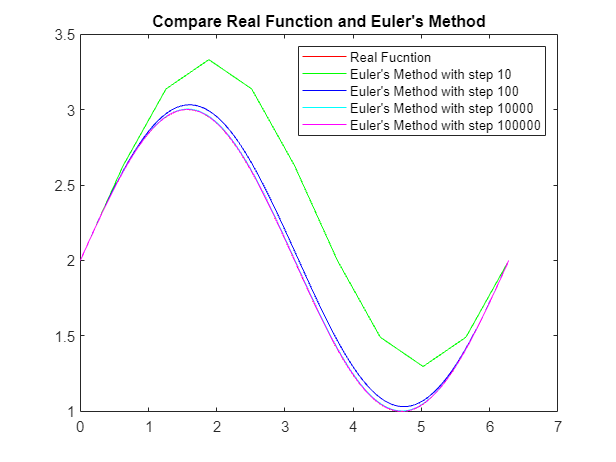

clearvars
clf
dydx = @(x, y)(cos(x));
y=@(x)(sin(x)+2);

x_0 = 0;
y_0 = 2;
x_stop = 2*pi;

% experiments of different steps
steps = [10, 100, 1000, 10000];
h = (x_stop-x_0)./steps;

% plot real function
plot(x_0:h(4):x_stop, y(x_0:h(4):x_stop), 'r')
hold on

colors = ['g', 'b', 'c', 'm'];
losses = [];
for i = 1:4
    [est_Y, loss] = euler_method(y, dydx, x_0, y_0, x_stop, h(i));
    losses(i) = abs(mean(loss));
    plot(x_0:h(i):x_stop, est_Y, colors(i));
end

title("Compare Real Function and Euler's Method");
legend(["Real Fucntion", ...
    "Euler's Method with step 10", ...
    "Euler's Method with step 100", ...
    "Euler's Method with step 10000", ...
    "Euler's Method with step 100000"], ...
    'Location','northeast');
hold off

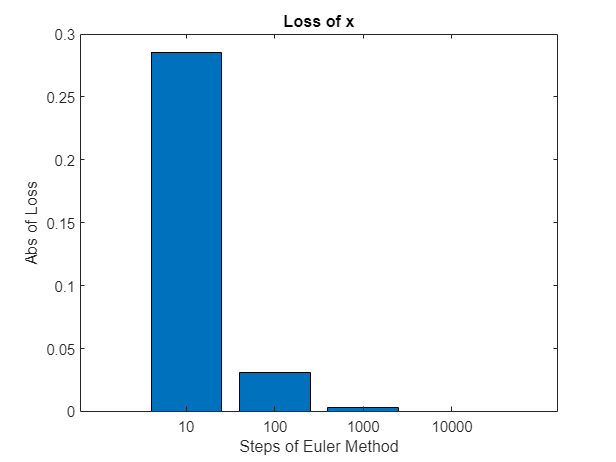


% draw loss
bar(losses)
set(gca,'XTickLabel',["10", "100", "1000", "10000"])
xlabel('Steps of Euler Method');
ylabel('Abs of Loss'); 
title("Loss of x")

## Function definition

function [est_Y, loss] = euler_method(realfunc, ode, x_0, y_0, x_stop, step)    %(x_0, y_0) is the initial point; [l, u] is an interval; n is how many split in the length of 1.
    % calculate
    est_Y = calc_euler(ode, x_0, y_0, x_stop, step);
    % evaluate
    loss = eval_euler(realfunc, est_Y, x_0, x_stop, step);
end 

function est_Y = calc_euler(ode, x_0, y_0, x_stop, step)
    interval = x_0:step:x_stop;
    est_Y = zeros(1, length(interval));
    est_Y(1) = y_0;
    for k = 2:length(interval)
        est_Y(k) = est_Y(k-1) + step * ode(interval(k-1), est_Y(k-1));
    end
end

function loss = eval_euler(realfunc, est_Y, x_0, x_stop, step)
    interval = x_0:step:x_stop;    
    real_Y = realfunc(interval);
    loss = real_Y - est_Y;
end